### 2.7.2020 example 

clear,clc;

x = randi(10,1,10)
x0 = x - mean(x);

y = randi(10,1,10)
y0 = y - mean(y);


SX = [];
for i=1:length(x)
    SX(i) = x0(i)^2;
end

% var(x) % <<<<<<<< sample variance (if calc manually, div by n-1 instead of n!)
% sum(SX)/(length(SX)-1)

SXY = [];
for i=1:length(x)
    SXY(i) = x0(i)*y0(i);
end

cov(x,y)
sum(SXY)/(length(SXY)-1)

### real data import

clear,clc;

load('ShulzeVorbModelDATA.mat') % folder: ece.kaya/MATLAB 

data = data - 100*1000;         % subtract the 100 ms before stim 
IRIs = diff(data,1,2);          % IRIs       
asyn = data - 450000;           % asynchrony

% data sample
I = IRIs(1,34:end)./1000;       % IRIs in miliseconds 
I = I';
N = length(I);

% tapping outlier removal
for i = 1:N
    if I(i) < 450 * 50/100 || I(i) > 450 * 150/100
        I(i) = [];
    end
end

## Wing & Kristofferson (1973) 

Wing, A. M., & Kristofferson, A. B. (1973). Response delays and the timing of discrete motor responses. *Perception & Psychophysics*, *14*(1), 5-12.

#### 
$${\mathrm{I}}_{\mathrm{j}} ={\mathrm{C}}_{\mathrm{j}} -{\mathrm{D}}_{\mathrm{j}-1} +{\mathrm{D}}_{\mathrm{j}}$$
                                         

Lag one covariance:


$$\begin{array}{l}
\gamma_I \left(1\right)=\mathrm{E}\left\lbrack \;\left({\mathrm{I}}_{\mathrm{j}} -\mu_{\mathrm{I}} \right)\left({\mathrm{I}}_{\mathrm{j}-1} -\mu_{\mathrm{I}} \right)\right\rbrack ;\\
\;\;\;\;\;\;\;\;\;={-\sigma^2 }_D 
\end{array}$$
 

Lag zero covariance:


$$\begin{array}{l}
\gamma_I \left(0\right)=\mathrm{E}\left\lbrack \;\left({\mathrm{I}}_{\mathrm{j}} -\mu_{\mathrm{I}} \right)\left({\mathrm{I}}_{\mathrm{j}} -\mu_{\mathrm{I}} \right)\right\rbrack ;\\
\;\;\;\;\;\;\;\;\;={\sigma^2 }_I \\
\;\;\;\;\;\;\;\;\;={\sigma^2 }_C +2{\sigma^2 }_D 
\end{array}$$


Lag one serial correlation:


$$\rho_I \left(1\right)=\frac{\gamma_I \left(1\right)}{\gamma_I \left(0\right)}\;$$


Timekeeper variance:


$${\sigma^2 }_{\mathrm{C}} =\gamma_{\mathrm{I}} \left(0\right)+2\gamma_{\mathrm{I}} \left(1\right)\;$$

$$\longrightarrow$$

$${{\mathrm{S}}^2 }_{\mathrm{C}} ={\mathrm{G}}_{\mathrm{I}} \left(0\right)+2{\mathrm{G}}_{\mathrm{I}} \left(1\right)$$


Motor variance:


$${\sigma^2 }_{\mathrm{D}} ={-\gamma }_{\mathrm{I}} \left(1\right)$$

$$\longrightarrow$$

$${{\mathrm{S}}^2 }_{\mathrm{D}} =-{\mathrm{G}}_{\mathrm{I}} \left(1\right)$$


Initialize two variables for lag-cov calculation

I_0 = I(1:end-1);
I_1 = I(2:end);

Long way 

lag_0 = sum((I_0 - mean(I_0)).*(I_0 - mean(I_0)))./ (length(I_0)-1);        % = var(I_0)
lag_1 = sum((I_1 - mean(I_1)).*(I_0 - mean(I_0)))./ (length(I_0)-1);        % = cov(I_0,I_1)

VAR_C = lag_0 + 2.*lag_1

VAR_C = 34.5542

VAR_D = -lag_1

VAR_D = 83.0302

Short way

clockvar = var(I_0) + 2.* cov(I_0,I_1);     
clockvar = clockvar(1,2)

clockvar = 34.5542

motorvar = -cov(I_0,I_1);
motorvar = motorvar(1,2)

motorvar = 83.0302

*Note: *


$$\left\lbrack \begin{array}{cc}
\mathrm{cov}\left(A,A\right) & \mathrm{cov}\left(A,B\right)\\
\mathrm{cov}\left(B,A\right) & \mathrm{cov}\left(B,B\right)
\end{array}\right\rbrack$$


Lag-1 autocorrelation (serial correlation) ($\rho_I \left(1\right)$):

acorr_1 = lag_1 ./ lag_0

acorr_1 = -0.4139

Autocovariance ([https://www.mathworks.com/matlabcentral/fileexchange/35915-autocovariance](https://www.mathworks.com/matlabcentral/fileexchange/35915-autocovariance))

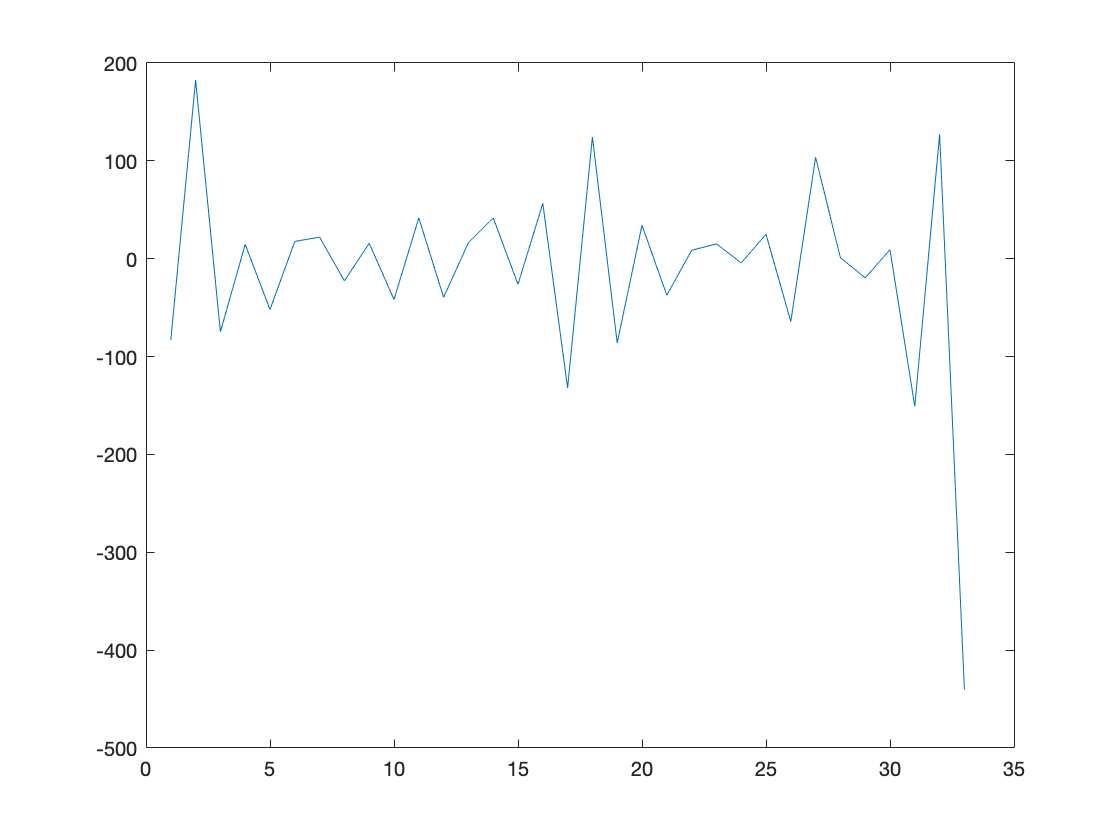

plot(autocov(I_1,I_0))

## Semjen, Schulz  & Vorberg (2000)

Semjen, A., Schulze, H. H., & Vorberg, D. (2000). Timing precision in continuation and synchronization tapping. *Psychological Research*, *63*(2), 137-147.

#### Base model:  $I_n =T_n +M_{n+1} -M_n$ 

#### Model with error correction:  $I_n =\left(T_n -\alpha A_n -\beta A_n \right)+M_{n+1} -M_n$ 

${\mathrm{I}}_{\mathrm{n}}$ : inter-response-interval (ITI)

${\mathrm{A}}_{\mathrm{n}}$: asynchrony (asyn = tap onset - metronome onset) 

    ${\mathrm{T}}_{\mathrm{n}}$: timekeeper / brain clock >> mean(T) & std(T)

    $\mathrm{M}$: motor delay >> mean(M) & std(M)

    $\alpha \;:$fixed proportion to subtract from the last sync. error

    $\beta :$fixed proportion to subtract from the next-to-the-last sync. error

Simulation

"We simulated self-paced and synchronized tapping from sequences of independent timekeeper intervals and motor delays, each variable generated from a gamma distribution with k 􏰇= 4 and scaled to give variances of m 􏰇= 5^2 and t 􏰇= 7^2 or 15^2. >> N = 34 x 800 for each parameter combination"

## ACVF = Compute autocovariance. https://www.mathworks.com/matlabcentral/fileexchange/24066-autocov-m

% Remove mean from x:
x = x - mean(x);
% For faster running time, we pre-allocate the output array:
acv = zeros(maxlag+1,1);
% Compute autocovariance:
for h = 0 : maxlag
   % Take matrix product of row vector and column vector to obtain a
   % scalar.  The row vector contains the first m-h elements of x; the
   % column vector contains the last m-h elements of x.
   acv(h+1)= x(1:m-h)' * x(1+h:m);
end
acv = acv / m;

## another eq from https://atmos.washington.edu/~breth/classes/AM582/lect/lect7-notes.pdf

lag-p ACVF which measures how strongly a time series is related with itself p samples later or earlier

## fit ?

p = [2 5]; 
X = 0:20; 
Yfcn = @(p,X) 1./(1+exp(-p(1).*(X-p(2)))); 

Y = Yfcn(p,X) + 0.1*randn(size(X)); 
	
[par fit]=fminsearch(@(p) norm(1./(1+exp(-p(1).*(X-p(2)))) -Y), [1,1])
figure(1)
plot(X, Y, 'p')
hold on
plot(X, Yfcn(par,X), '-r')
hold off
grid

% find the parameters where observed values are closest to expected values
% (function)

## youtube

x = [];
x(1) = 0;
for i = 2:1000
    x(i) = x(i-1)+normrnd(0,1);
end

rndwalk = timeseries(x);
plot(rndwalk);
autocorr(x)

% it is not stationary >> no point of taking ACF >> remove trend by diff

plot(diff(x))
autocorr(diff(x))